# Quantum Gates [--- Draft ---]

## Simulating IBM's Quantum Experience with FockBox

[*Matthias Wolff*](https://www.b-tu.de/en/fg-kommunikationstechnik/team/staff/prof-dr-ing-habil-matthias-wolff)

[BTU Cottbus-Senftenberg](https://www.b-tu.de/en/), [Chair of Communications Enginerring](https://www.b-tu.de/en/fg-kommunikationstechnik)

fock.addFockBoxPaths();

## 1   Some Elementary Quantum Cicuits

***[TODO: ...]***

See Appendix A for a list of quantum gates.

## 2   Toffoli Gate (CCNOT)

The Toffoli or CCNOT gate is a controlled negator with two controlling qubits and one target qubit. Its circuit representation is

        ***[TODO: picture]***

The controlling qubits are $q[0]$ and $q[1]$, the controlled one is $q[2]$ (other combinations are possible). The function of the gate is to flip $q[2]$ iff $q[0]$ and $q[1]$ are both $|1\rangle$ and to leave $q[2]$ alone otherwise. The respective operator matrix is

        ***[TODO: picture]***

**2.1   Building the Toffoli Gate on IBM QX**

As IBM Quantum Experience does not natively support the Toffoli gate, it must be implemented as a circuit of elementary gates as follows [1]

        ***[TODO: picture]***

We simulate the function of this quantum cicuit by computing the resulting operator using FookBox. To this end, we first get the required elementary gates from the library.

b0     = ibmqx.b0;          % |0> ket
I      = ibmqx.id;          % Identity gate operator (i.e., a wire)
X      = ibmqx.X;           % Pauli-X gate operator
H      = ibmqx.H;           % Hadamard gate operator
T      = ibmqx.T;           % T phase shift gate operator
CNOT02 = ibmqx.CNOT(3,0,2); % CNOT gate operator (control: q[0], target: q[2])
CNOT12 = ibmqx.CNOT(3,1,2); % CNOT gate operator (control: q[1], target: q[2])

Then, we compose the $\mbox{CCNOT}_{0,1,2}$ gate operator. Note that the quantum circuit reads from left to right, but the respective operators must be multiplied from right to left.

% CCNOT gate (controls: q[0] and q[1], target: q[2])
%       q[]  2  1  0
CCNOT012 =   CNOT12    ...  % slot 23
         * [ H  H  I ] ...  % slot 22
         *   CNOT12    ...  % slot 21
         * [ H  H  I ] ...  % slot 20
         *   CNOT12    ...  % slot 19
         *   CNOT02    ...  % slot 18
         * [ T' I  T ] ...  % slot 17
         *   CNOT02    ...  % slot 16
         *   CNOT12    ...  % slot 15
         * [ H  H  I ] ...  % slot 14
         *   CNOT12    ...  % slot 13
         * [ H  H  I ] ...  % slot 12
         *   CNOT12    ...  % slot 11
         * [ H  I  I ] ...  % slot 10
         * [ T  T  I ] ...  % slot 9
         *   CNOT02    ...  % slot 8
         * [ T' I  I ] ...  % slot 7
         *   CNOT12    ...  % slot 6
         * [ T  I  I ] ...  % slot 5
         *   CNOT02    ...  % slot 4
         * [ T' I  I ] ...  % slot 3
         *   CNOT12    ...  % slot 2
         * [ H  I  I ];     % slot 1
CCNOT012 = round(CCNOT012*1e10)*1e-10; % Very mild rounding 
CCNOT012.name = 'Toffoli gate (controls: q[0] and q[1], target: q[2])';
ibmqx.disp(CCNOT012);

  ibmqx quantum gate operator

    Name  : Toffoli gate (controls: q[0] and q[1], target: q[2])
    Qubits: 3

          <000| <001| <010| <011| <100| <101| <110| <111|
    |000>     1     0     0     0     0     0     0     0
    |001>     0     1     0     0     0     0     0     0
    |010>     0     0     1     0     0     0     0     0
    |011>     0     0     0     0     0     0     0     1
    |100>     0     0     0     0     1     0     0     0
    |101>     0     0     0     0     0     1     0     0
    |110>     0     0     0     0     0     0     1     0
    |111>     0     0     0     1     0     0     0     0


fprintf('Underlying FockBox object:\n');

Underlying FockBox object:


disp(CCNOT012);

  fockobj

    Name: Toffoli gate (controls: q[0] and q[1], target: q[2]) 
    Type: linear operator 

    (0⊗0⊗0,0⊗0⊗0)       	1.000000
    (0⊗0⊗1,0⊗0⊗1)       	1.000000
    (0⊗1⊗0,0⊗1⊗0)       	1.000000
    (1⊗1⊗1,0⊗1⊗1)       	1.000000
    (1⊗0⊗0,1⊗0⊗0)       	1.000000
    (1⊗0⊗1,1⊗0⊗1)       	1.000000
    (1⊗1⊗0,1⊗1⊗0)       	1.000000
    (0⊗1⊗1,1⊗1⊗1)       	1.000000


**2.2   Doing Some Boolean Qubit Logic**

First, here is how to short-cut building the Toffoli gate in FockBox:

CCNOT = ibmqx.CU(ibmqx.CU(X,'U*'),'U*'); 
CCNOT.name = 'CCNOT (X**)';
ibmqx.disp(CCNOT);

  ibmqx quantum gate operator

    Name  : CCNOT (X**)
    Qubits: 3

          <000| <001| <010| <011| <100| <101| <110| <111|
    |000>     1     0     0     0     0     0     0     0
    |001>     0     1     0     0     0     0     0     0
    |010>     0     0     1     0     0     0     0     0
    |011>     0     0     0     0     0     0     0     1
    |100>     0     0     0     0     1     0     0     0
    |101>     0     0     0     0     0     1     0     0
    |110>     0     0     0     0     0     0     1     0
    |111>     0     0     0     1     0     0     0     0


Like above, the control qubits are $q[0]$ and $q[1]$, the target is $q[2]$. Now we simulate a quantum circuit computing $q[2]=q[0]\cdot q[1]$, i.e. the conjuction of the control qubits. The circuit starts in state $|\Psi\rangle = |000\rangle$, i.e., all qubits are zero (slot 0). To get the whole truth table at once, we use the Hadamard gate on the control qubits which gets them into a superposition state (slot 1). In slot 3, the Toffoli gate computes the conjunction.

% Quantum circuit for q[2] = q[0] AND q[1]
%  q[]  2  1  0
Psi = [b0 b0 b0]    ; Psi.name = 'slot 0'; %ibmqx.disp(Psi);
Psi = [ I H  H ]*Psi; Psi.name = 'slot 1'; %ibmqx.disp(Psi);
Psi =   CCNOT   *Psi; Psi.name = 'slot 2'; %ibmqx.disp(Psi);

As we execute the circuit step by step, the operations are in forward order. Uncomment the `ibmqx.disp` commands watch the state of the cicuit evolve. Now let's se what we have got...

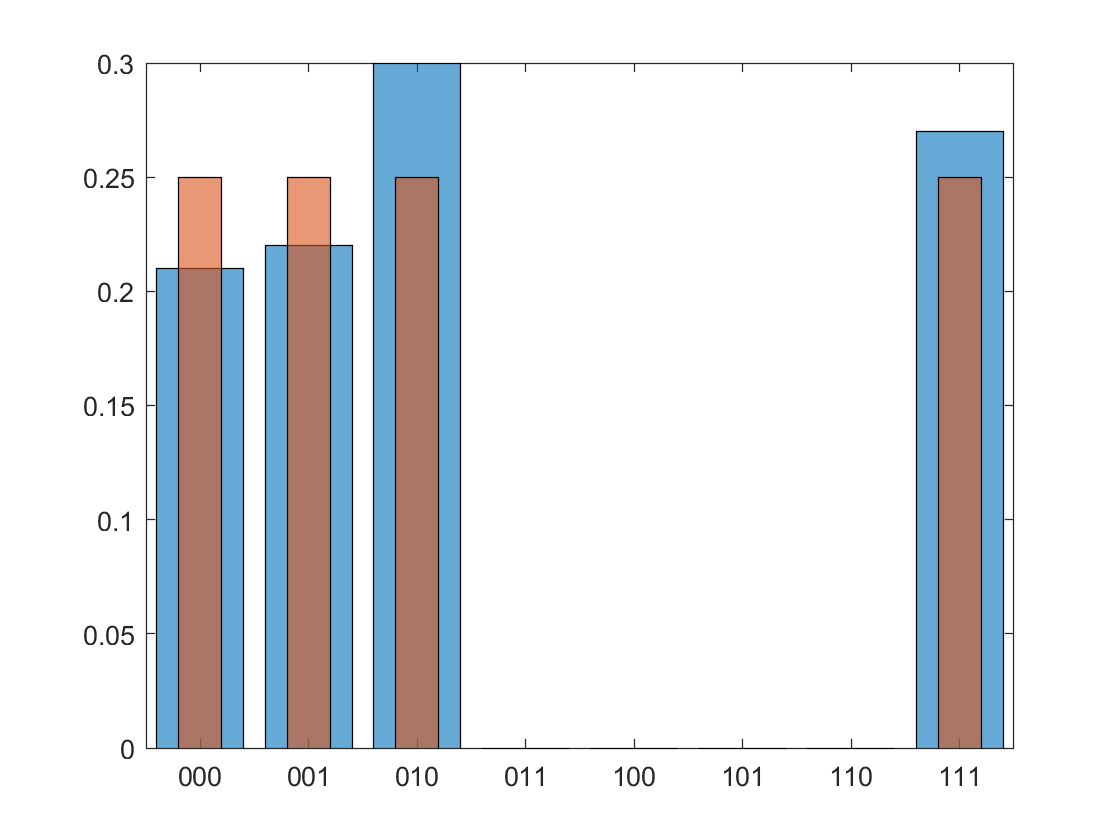

ibmqx.probe(Psi,[2 1 0],100);

... the whole truth table. Note that the result $q[1]\cdot q[0]$ is in the leftmost position. Instead of FockBox' `CCNOT` we could as well have used the IBM QX version `CCNOT012` from above. They are equal.

***[TODO: Other Boolean ops. by negating one or several inputs and/or the output]***

## 3   Building Arbitrary Controlled Gates (only in FockBox)

% Make two CNOT gates
CNOT01 = ibmqx.CU(ibmqx.X,'*U'); ibmqx.disp(CNOT01);

  ibmqx quantum gate operator

    Name  : *(Pauli-X)
    Qubits: 2

         <00| <01| <10| <11|
    |00>    1    0    0    0
    |01>    0    1    0    0
    |10>    0    0    0    1
    |11>    0    0    1    0


CNOT10 = ibmqx.CU(ibmqx.X,'U*'); ibmqx.disp(CNOT10);

  ibmqx quantum gate operator

    Name  : (Pauli-X)*
    Qubits: 2

         <00| <01| <10| <11|
    |00>    1    0    0    0
    |01>    0    0    0    1
    |10>    0    0    1    0
    |11>    0    1    0    0



% Make four CCNOT gates (only three of them different)
ibmqx.disp(ibmqx.CU(CNOT01,'*U'));

  ibmqx quantum gate operator

    Name  : *(*(Pauli-X))
    Qubits: 3

          <000| <001| <010| <011| <100| <101| <110| <111|
    |000>     1     0     0     0     0     0     0     0
    |001>     0     1     0     0     0     0     0     0
    |010>     0     0     1     0     0     0     0     0
    |011>     0     0     0     1     0     0     0     0
    |100>     0     0     0     0     1     0     0     0
    |101>     0     0     0     0     0     1     0     0
    |110>     0     0     0     0     0     0     0     1
    |111>     0     0     0     0     0     0     1     0


ibmqx.disp(ibmqx.CU(CNOT10,'*U'));

  ibmqx quantum gate operator

    Name  : *((Pauli-X)*)
    Qubits: 3

          <000| <001| <010| <011| <100| <101| <110| <111|
    |000>     1     0     0     0     0     0     0     0
    |001>     0     1     0     0     0     0     0     0
    |010>     0     0     1     0     0     0     0     0
    |011>     0     0     0     1     0     0     0     0
    |100>     0     0     0     0     1     0     0     0
    |101>     0     0     0     0     0     0     0     1
    |110>     0     0     0     0     0     0     1     0
    |111>     0     0     0     0     0     1     0     0


ibmqx.disp(ibmqx.CU(CNOT01,'U*'));

  ibmqx quantum gate operator

    Name  : (*(Pauli-X))*
    Qubits: 3

          <000| <001| <010| <011| <100| <101| <110| <111|
    |000>     1     0     0     0     0     0     0     0
    |001>     0     1     0     0     0     0     0     0
    |010>     0     0     1     0     0     0     0     0
    |011>     0     0     0     1     0     0     0     0
    |100>     0     0     0     0     1     0     0     0
    |101>     0     0     0     0     0     0     0     1
    |110>     0     0     0     0     0     0     1     0
    |111>     0     0     0     0     0     1     0     0


ibmqx.disp(ibmqx.CU(CNOT10,'U*'));

  ibmqx quantum gate operator

    Name  : ((Pauli-X)*)*
    Qubits: 3

          <000| <001| <010| <011| <100| <101| <110| <111|
    |000>     1     0     0     0     0     0     0     0
    |001>     0     1     0     0     0     0     0     0
    |010>     0     0     1     0     0     0     0     0
    |011>     0     0     0     0     0     0     0     1
    |100>     0     0     0     0     1     0     0     0
    |101>     0     0     0     0     0     1     0     0
    |110>     0     0     0     0     0     0     1     0
    |111>     0     0     0     1     0     0     0     0


## Appendix A: Gate Operators

**A.1   Physical Single Qubit Gates**

    U1: $\left(\begin{array}{ccc}
& |0\rangle &  |1\rangle\\
|0\rangle & 1 & 0 \\
|1\rangle & 0 & \mathrm{e}^{\mathrm{i\,\lambda}}
\end{array}\right)$       U2: ***[TODO...]***

**A.2   Pauli Gates**

    

***[TODO...]***

**A.3   CNOT Gate**

The CNOT (controlled-NOT) gate is a physical double qubit gate of IBM Qauntum Experience [1]. Its operator in a quantum circuit of $N$ qubits---where $q[c$] is the controlling qubit and $q[t]$ is the target qubit---is

    
$$\mbox{CNOT}_{N,c,t}
  = \bigotimes\limits_{i=1}^{N} O_{1,i}
  + \bigotimes\limits_{i=1}^{N} O_{2,i}$$


with   $O_{1,i}
= \begin{cases}
     |0\rangle\langle 0| & N-i=c\\
     I & \mbox{otherwise}
   \end{cases}$   and   $O_{2,i}
= \begin{cases}
     |1\rangle\langle 1| & N-i=c\\
     X &N-i=t\\
     I & \mbox{otherwise.}
   \end{cases}$

Here, $I=|0\rangle\langle 0| + 1\rangle\langle 1|$ denotes the identity gate operator and $X=|0\rangle\langle 1| + |1\rangle\langle 0|$ the Pauli-X gate operator. This operator is created by the `ibmqx.CNOT(N,c,t)` function.

## References

[1] IBM Q Experience. Online: [https://quantumexperience.ng.bluemix.net,](https://quantumexperience.ng.bluemix.net,) Retrieved Aug. 15, 2018.